# Problem - 1}

% Calculate alpha
alpha = 1 + mod(238, 3);

## Q-1]

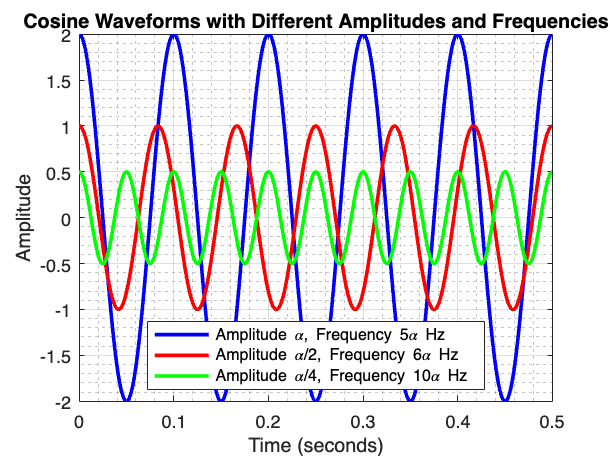

% Time vector
t = linspace(0, 1/alpha, 1000); % 1000 points for smoother plot

% Waveforms
waveform_a = alpha * cos(2 * pi * 5 * alpha * t);
waveform_b = (alpha/2) * cos(2 * pi * 6 * alpha * t);
waveform_c = (alpha/4) * cos(2 * pi * 10 * alpha * t);

% Plotting
plot(t, waveform_a, 'b', 'LineWidth', 2, 'DisplayName', 'Amplitude \alpha, Frequency 5\alpha Hz');
hold on;
plot(t, waveform_b, 'r', 'LineWidth', 2, 'DisplayName', 'Amplitude \alpha/2, Frequency 6\alpha Hz');
plot(t, waveform_c, 'g', 'LineWidth', 2, 'DisplayName', 'Amplitude \alpha/4, Frequency 10\alpha Hz');
hold off;

title('Cosine Waveforms with Different Amplitudes and Frequencies');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('Location', 'best');
grid on;
grid minor;

## Q-2]

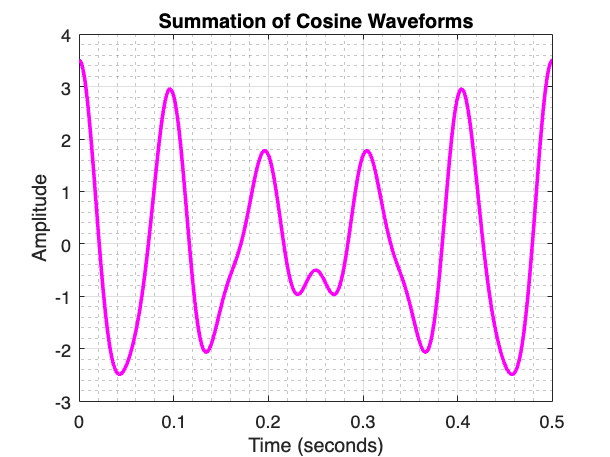

% Summation of waveforms
total_waveform = waveform_a + waveform_b + waveform_c;

% Plotting
figure;
plot(t, total_waveform, 'm', 'LineWidth', 2);
title('Summation of Cosine Waveforms');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;
grid minor;

## Q-3]

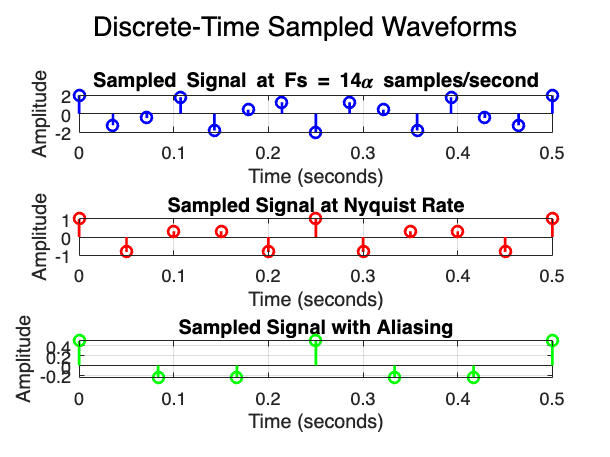

% Time vector
t_continuous = linspace(0, 1/alpha, 1000); % Continuous time vector

% Sampling frequencies
Fs_a = 14 * alpha;
Fs_b = 10 * alpha; % Nyquist rate for the highest frequency (10*alpha) component
Fs_c = 6 * alpha;  % Aliasing condition: 6*alpha Hz aliased to 3*alpha Hz

% Discrete-time sampled signals
n_a = 0:(1/Fs_a):(1/alpha);
n_b = 0:(1/Fs_b):(1/alpha);
n_c = 0:(1/Fs_c):(1/alpha);

signal_a = alpha * cos(2 * pi * 5 * alpha * n_a);
signal_b = (alpha/2) * cos(2 * pi * 6 * alpha * n_b);
signal_c = (alpha/4) * cos(2 * pi * 10 * alpha * n_c);

% Plotting
figure;

subplot(3,1,1);
stem(n_a, signal_a, 'b', 'LineWidth', 1.5);
title('Sampled Signal at Fs = 14\alpha samples/second');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
stem(n_b, signal_b, 'r', 'LineWidth', 1.5);
title('Sampled Signal at Nyquist Rate');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

subplot(3,1,3);
stem(n_c, signal_c, 'g', 'LineWidth', 1.5);
title('Sampled Signal with Aliasing');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;

sgtitle('Discrete-Time Sampled Waveforms');

## Q-4]

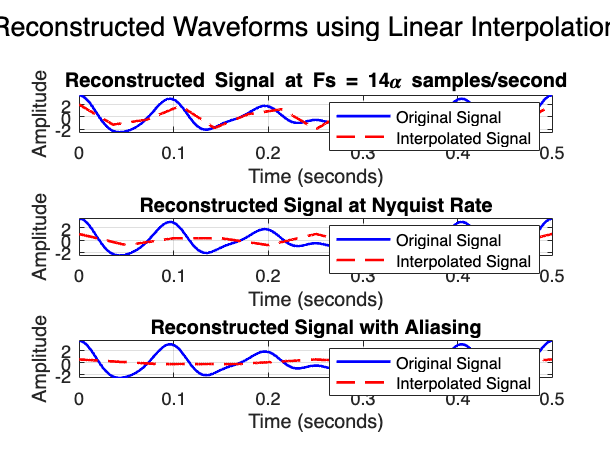

% Linear interpolation
t_interpolate = linspace(0, 1/alpha, 10000); % Interpolation points
interp_signal_a = interp1(n_a, signal_a, t_interpolate, 'linear');
interp_signal_b = interp1(n_b, signal_b, t_interpolate, 'linear');
interp_signal_c = interp1(n_c, signal_c, t_interpolate, 'linear');

% Plotting
figure;
subplot(3,1,1);
plot(t_continuous, total_waveform, 'b', 'LineWidth', 1.5);
hold on;
plot(t_interpolate, interp_signal_a, 'r--', 'LineWidth', 1.5);
hold off;
title('Reconstructed Signal at Fs = 14\alpha samples/second');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('Original Signal', 'Interpolated Signal');
grid on;

subplot(3,1,2);
plot(t_continuous, total_waveform, 'b', 'LineWidth', 1.5);
hold on;
plot(t_interpolate, interp_signal_b, 'r--', 'LineWidth', 1.5);
hold off;
title('Reconstructed Signal at Nyquist Rate');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('Original Signal', 'Interpolated Signal');
grid on;

subplot(3,1,3);
plot(t_continuous, total_waveform, 'b', 'LineWidth', 1.5);
hold on;
plot(t_interpolate, interp_signal_c, 'r--', 'LineWidth', 1.5);
hold off;
title('Reconstructed Signal with Aliasing');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('Original Signal', 'Interpolated Signal');
grid on;

sgtitle('Reconstructed Waveforms using Linear Interpolation');

## Q-5]

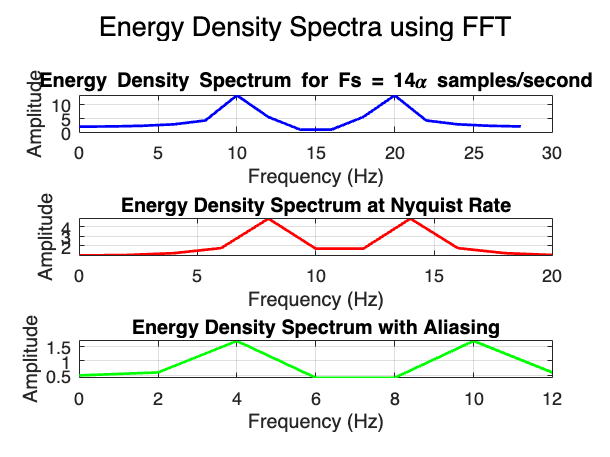

% FFT and frequency vector
fft_a = abs(fft(signal_a));
fft_b = abs(fft(signal_b));
fft_c = abs(fft(signal_c));

frequencies_a = linspace(0, Fs_a, length(fft_a));
frequencies_b = linspace(0, Fs_b, length(fft_b));
frequencies_c = linspace(0, Fs_c, length(fft_c));

% Plotting
figure;

subplot(3,1,1);
plot(frequencies_a, fft_a, 'b', 'LineWidth', 1.5);
title('Energy Density Spectrum for Fs = 14\alpha samples/second');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
plot(frequencies_b, fft_b, 'r', 'LineWidth', 1.5);
title('Energy Density Spectrum at Nyquist Rate');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

subplot(3,1,3);
plot(frequencies_c, fft_c, 'g', 'LineWidth', 1.5);
title('Energy Density Spectrum with Aliasing');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

sgtitle('Energy Density Spectra using FFT');

# Problem - 2}


% Frequencies for "Do Re Mi Fa So La Ti Do" in Hz
frequencies = [261.63, 293.66, 329.63, 349.23, 392.00, 440.00, 493.88, 523.25];

% Duration of each tone in seconds
tone_duration = 1;

% Create a time vector for each tone
t = linspace(0, tone_duration, tone_duration * 44100); % Using a sampling rate of 44100 Hz (CD quality)

% Generate tones at different frequencies
tones = zeros(length(frequencies), length(t));
for i = 1:length(frequencies)
    tones(i, :) = sin(2 * pi * frequencies(i) * t);
end

% Append the tones together
sequence = reshape(tones', 1, []);

% Save the sequence as a .wav file
audiowrite('music_sequence.wav', sequence, 44100);

% Listen to the audio
sound(sequence, 44100);





# Problem - 3}


% Load the original audio file
filename = 'Track001.wav';
[y, original_fs] = audioread(filename);

% Different downsampling factors
downsampling_factors = [2, 3, 4];

% Perform downsampling and listen to the audio
for i = 1:length(downsampling_factors)
    factor = downsampling_factors(i);
    
    % Downsample
    downsampled_signal = downsample(y, factor);
    new_fs = original_fs / factor;
    
    % Save the downsampled signal as a .wav file
    output_filename = sprintf('downsampled_%dx.wav', factor);
    audiowrite(output_filename, downsampled_signal, new_fs);
    
    % Listen to the downsampled audio
    sound(downsampled_signal, new_fs);
    pause(length(downsampled_signal) / new_fs + 0.5); % Pause to hear the audio
end

% Upsampling while preserving frequency content
upsampling_factor = 2;

% Perform upsampling
upsampled_signal = ifft(fft(y) .* [ones(1, upsampling_factor), zeros(1, length(y) * (upsampling_factor - 1))]);

Requested 811631x811633 (9816.1GB) array exceeds maximum array size preference (16.0GB). This might cause MATLAB to become unresponsive.

Related documentation


% Normalize the amplitude to match the original signal
upsampled_signal = upsampled_signal / max(abs(upsampled_signal)) * max(abs(y));

% Save the upsampled signal as a .wav file
output_filename = sprintf('upsampled_%dx.wav', upsampling_factor);
audiowrite(output_filename, upsampled_signal, original_fs);

% Listen to the upsampled audio
sound(upsampled_signal, original_fs);


